% Create a hornConical antenna
% Generated by MATLAB(R) 9.14 and Antenna Toolbox 5.4.
% Generated on: 15-May-2023 23:06:56

## Antenna Properties

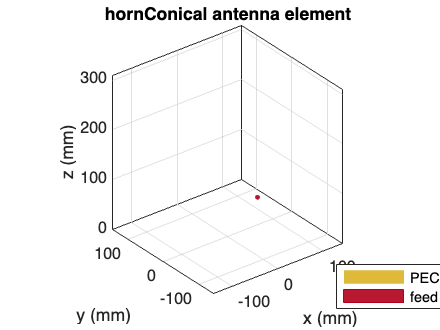

antennaObject = design(hornConical, 1700*1e6);
antennaObject.ConeHeight = 0.11543;
antennaObject.ApertureRadius = 0.1185;
antennaObject.Tilt = -90;
% Show
figure;
show(antennaObject)

## Antenna Analysis

Define plot frequency 

plotFrequency = 1700*1e6;
% Define frequency range 
freqRange = (1530:17:1870)*1e6;
% Reference Impedance 
refImpedance = 50;
% pattern
figure;
pattern(antennaObject, plotFrequency)
% azimuth
figure;
patternAzimuth(antennaObject, plotFrequency, 0, 'Azimuth', 0:5:360)
% elevation
figure;
patternElevation(antennaObject, plotFrequency,0,'Elevation',0:5:360)